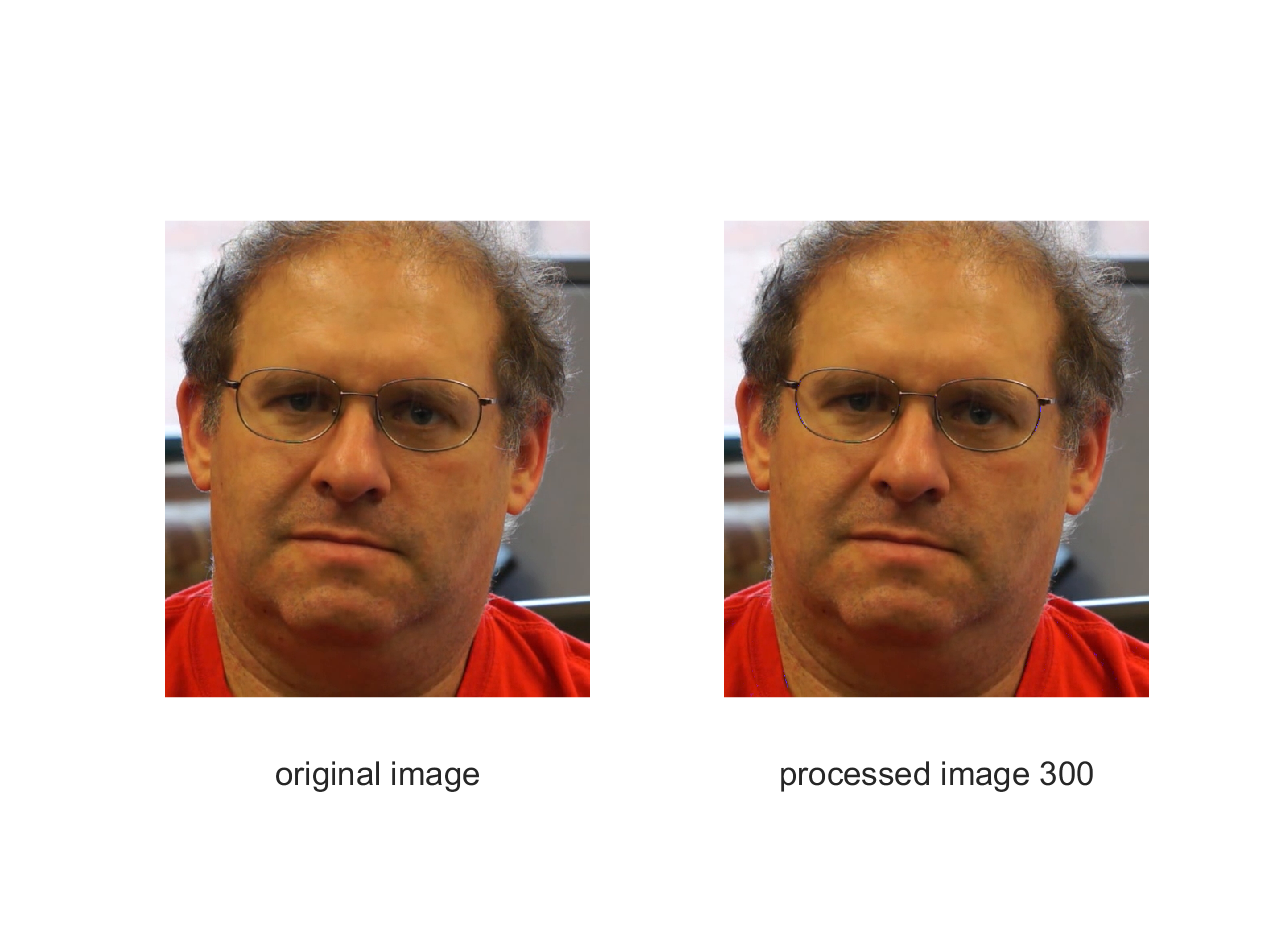

clear;
clc;
video=load('rgb_video_values.mat');

% downsample the video images for debugging and testing by a factor of (downsample_by_M)
% IMPORTANT: Set downsample_by_M = 1 for your final project results.
downsample_by_M = 5;
if (downsample_by_M > 5) 
    rgb_images = reshape(video.imageStack_uint8,[video.rows,video.cols,3,video.num_frames]);
    rgb_small = rgb_images(1:downsample_by_M:video.rows,1:downsample_by_M:video.cols,:);
    video.cols = floor((video.cols+1)/downsample_by_M);
    video.rows = floor((video.rows+1)/downsample_by_M);
    video.imageStack_uint8 = reshape(rgb_small,[video.rows*video.cols*3,video.num_frames]);
end

x_of_n = video.imageStack_uint8;

% REPLACE CODE HERE TO SET THE VALUE OF y_of_n and set your own alpha value
n1=-50:50;
h_n = sin(pi*2*0.83*n1.*(1/30));
alpha = 3;
y_of_n = conv2(x_of_n,fliplr(h_n), "same");
%end of my code

rgb_images = reshape(x_of_n,[video.rows,video.cols,3,video.num_frames]);
rgb_processed = reshape(y_of_n,[video.rows,video.cols,3,video.num_frames]);
new_rgb_images = rgb_images + uint8(alpha*rgb_processed);
for frame=1:video.num_frames
    figure(1), subplot(1,2,1), imshow(rgb_images(:,:,:,frame),'InitialMagnification', 'fit'), xlabel('original image');
    framestr = sprintf('processed image %d',frame);
    figure(1), subplot(1,2,2), imshow(new_rgb_images(:,:,:,frame),'InitialMagnification', 'fit'), xlabel(framestr);
    pause(1/30);
end

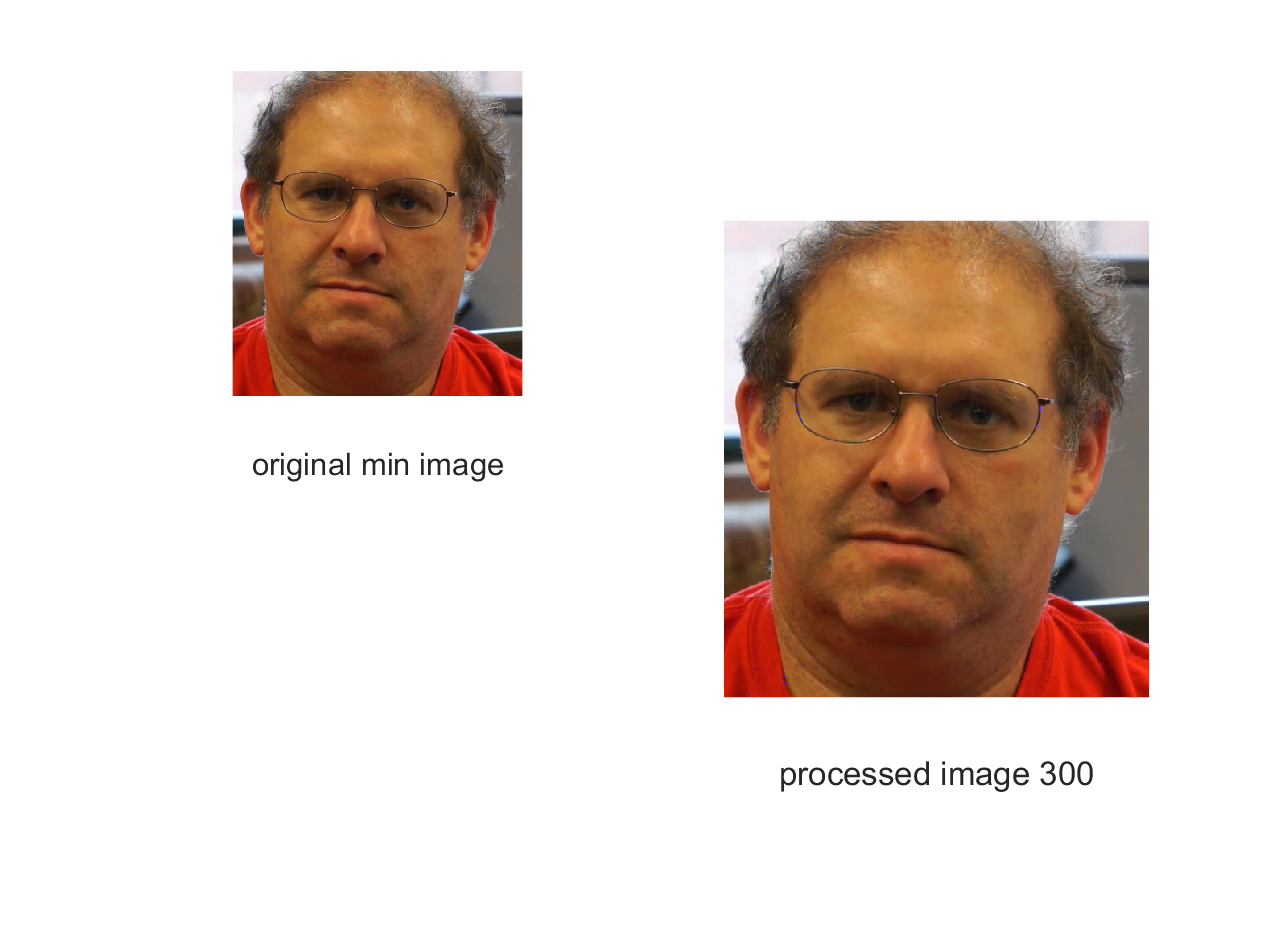


minframe = 188;
maxframe = 104;
figure(2), subplot(2,2,1), imshow(rgb_images(:,:,:,minframe)), xlabel('original min image');

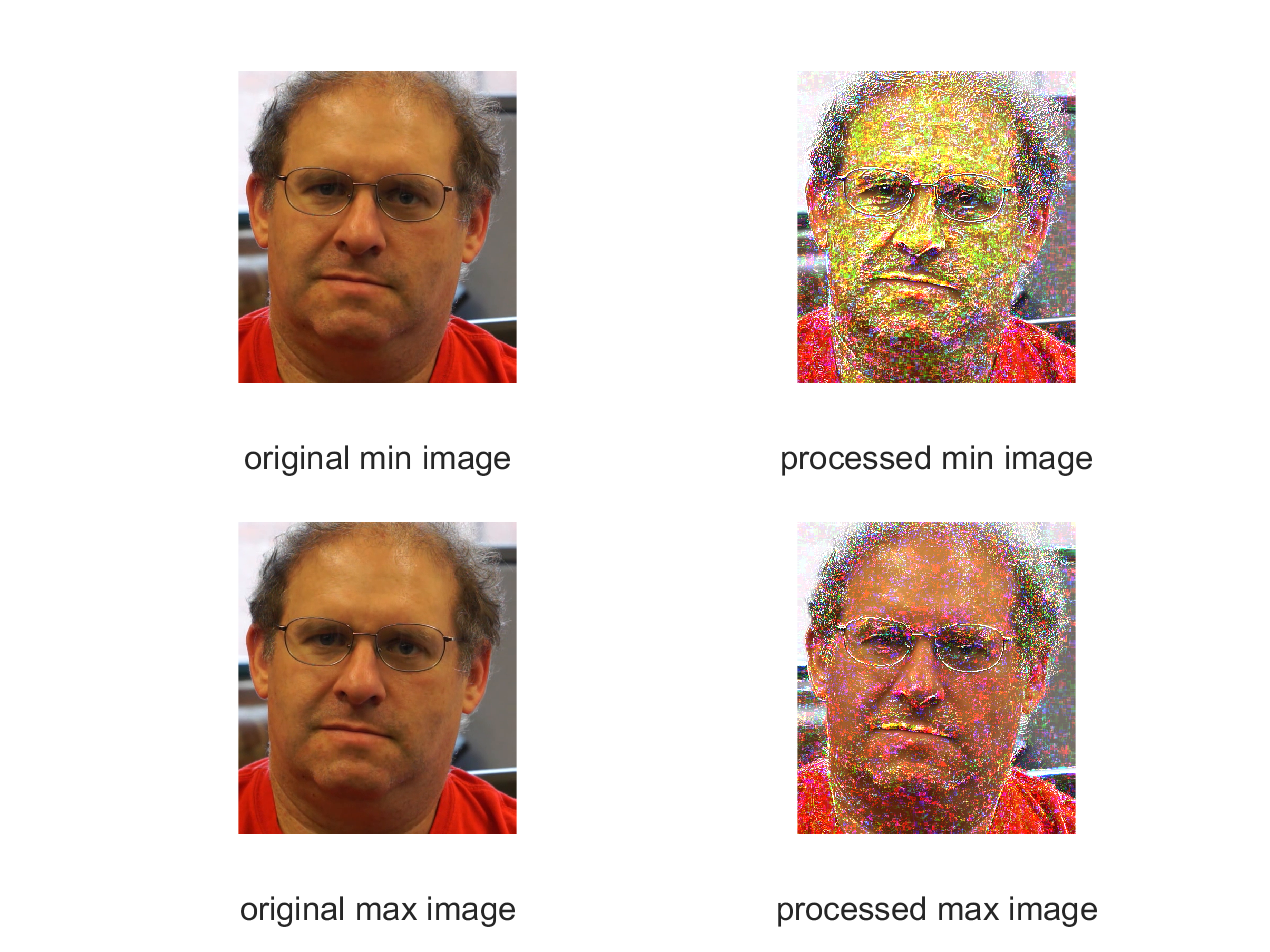

figure(2), subplot(2,2,2), imshow(new_rgb_images(:,:,:,minframe)), xlabel('processed min image');
figure(2), subplot(2,2,3), imshow(rgb_images(:,:,:,maxframe)), xlabel('original max image');
figure(2), subplot(2,2,4), imshow(new_rgb_images(:,:,:,maxframe)), xlabel('processed max image');